# **Effet d'une arthroplastie totale inversée d'épaule sur les synergies musculaires**

**Analyse EMG**

clc; close all; clear all; %#ok<CLALL>

*Notice d'information sur les muscles étudiés*

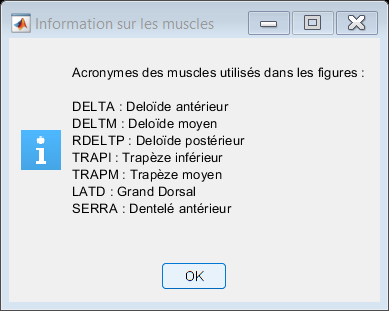

info_message = sprintf(['Acronymes des muscles utilisés dans les figures :\n\n' ... 
'DELTA : Deloïde antérieur\n' ... 
'DELTM : Deloïde moyen\n' ... 
'RDELTP : Deloïde postérieur\n' ... 
'TRAPM : Trapèze moyen\n' ... 
'TRAPS : Trapèze supérieur\n' ... 
'LATD : Grand Dorsal\n' ... 
'SERRA : Dentelé antérieur\n\n']); 
msgbox(info_message, 'Information sur les muscles', 'help');

*Définition des variables du protocole*

% Ajout de la bibliothèque btk
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition des sujets
subjects = {'MF01', 'TF02', 'YL03', 'RF05', 'AP06'};
nb_subjects = length(subjects);

% Définition des muscles 
muscles = {'RDELTA', 'RDELTM', 'RDELTP', 'RTRAPM', 'RTRAPS', 'RLATD', 'RSERRA'};
nb_muscles = length(muscles);

% Définition des labels pour les tâches
functional_labels = {...
    'Porter les mains à la bouche', ...
    'Toucher le haut de la tête', ...
    'Porter les mains le plus haut possible au-dessus de la tête', ...
    'Porter les mains le plus haut possible le long de la colonne vertébrale'};

analytic_labels = {...
    'Flexion (élévation sagittale)', ...
    'Abduction (élévation coronale)', ...
    'Rotation externe (abduction 0°)', ...
    'Rotation interne (abduction 0°)', ...
    'Élévation dans le plan scapulaire'};

nb_functional = length(functional_labels);
nb_analytics = length(analytic_labels);

*Paramètrage du traitement des données électromyographiques brutes*

% Paramètres
fs = 2000; % Fréquence d'échantillonnage
[b, a] = butter(4, [15, 475] / (fs/2), 'bandpass'); % Filtre Butterwoth passe-bande
rms_window = round(0.250 * fs); % Fenêtre Root Mean Sqaure
num_points = 1000; % Normalisation du temps sur 1000 points
time_normalized = linspace(0, 1, num_points);

**Traitement des données des mouvements fonctionelles**

for subj_idx = 1:nb_subjects
    for f_idx = 1:nb_functional
        % Chargement des données
        fileName = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
            '%s-%s-20240101-PROTOCOL01-FUNCTIONAL%d-.c3d'], ...
            subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, f_idx);

        c3dH = btkReadAcquisition(fileName);
        analogs = btkGetAnalogs(c3dH);
        
        % figure;
        sgtitle(sprintf('Sujet %s - %s', subjects{subj_idx}, functional_labels{f_idx}));
        
        for m = 1:nb_muscles
            subplot(ceil(nb_muscles/2), 2, m);
            muscle_name = muscles{m};
            if isfield(analogs, muscle_name)
                signal = analogs.(muscle_name);
                time_original = linspace(0, 1, length(signal));
                
                % 1) Filtrage passe-bande
                signal_filtered = filtfilt(b, a, signal);
                % 2) Rectification
                signal_abs = abs(signal_filtered);
                % 3) Lissage avec Root Mean Square
                emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
                % 4) Normalisation par maximum de chaque cycle
                num_cycles = 3;
                cycle_length = floor(length(emg_rms) / num_cycles);
                emg_normalized = zeros(size(emg_rms));
                for cycle = 1:num_cycles
                    start_idx = (cycle - 1) * cycle_length + 1;
                    end_idx = min(start_idx + cycle_length - 1, length(emg_rms));
                    sorted_vals = sort(emg_rms(start_idx:end_idx), 'descend');
                    mvc_peak_avg = mean(sorted_vals(1:5));
                    if mvc_peak_avg ~= 0
                        emg_normalized(start_idx:end_idx) = (emg_rms(start_idx:end_idx) / mvc_peak_avg) * 100;
                    end
                end

                % 5) Interpolation sur l'axe temporel normalisé
                interp_signal_functional = interp1(time_original, emg_normalized, time_normalized, 'spline');
                
                all_functional_data{subj_idx, f_idx, m} = interp_signal_functional;
                
                % Affichage des données "FUNCTIONAL" traitées (si nécessaire)
                % plot(time_normalized, interp_signal_functional, 'LineWidth', 1.2);
                title(muscle_name);
                xlabel('Temps normalisé (0 à 1)');
                ylabel('EMG (% max)');
                grid on;
            else
                title(sprintf('%s (Données absentes)', muscle_name));
            end
        end
    end
end

**Comparasions des données fonctionelles **

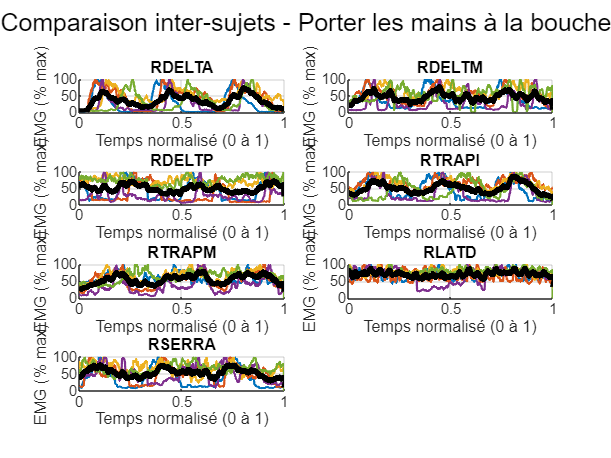

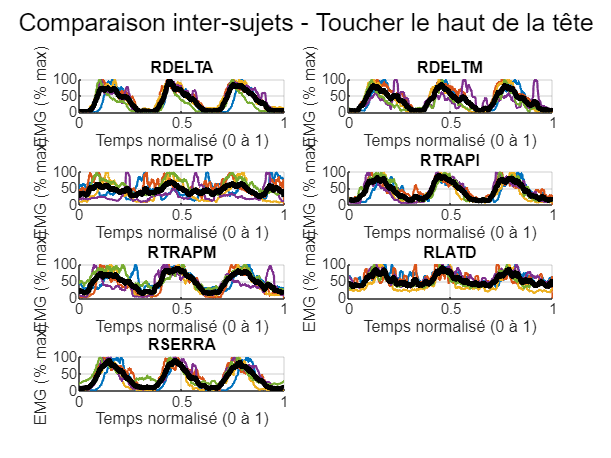

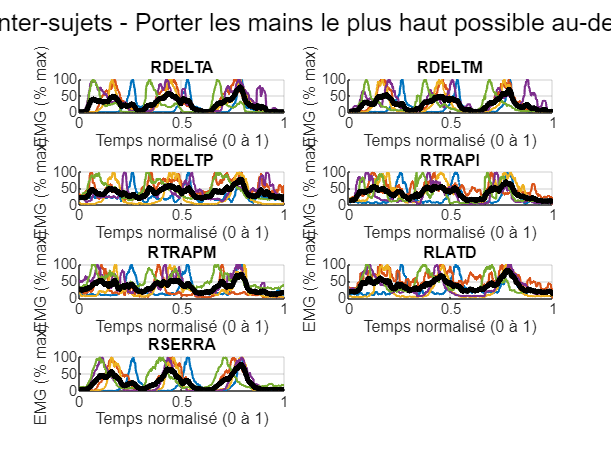

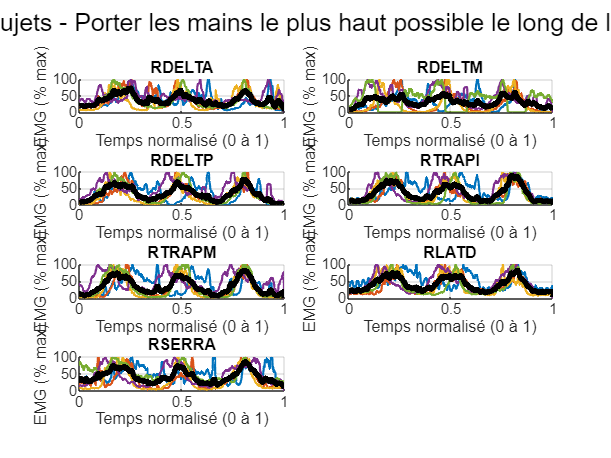

global_profiles_functional = cell(nb_functional, nb_muscles);

for f_idx = 1:nb_functional
    figure;
    sgtitle(sprintf('Comparaison inter-sujets - %s', functional_labels{f_idx}));
    
    for m = 1:nb_muscles
        all_subjects_matrix = [];  % Pour stocker les signaux de tous les sujets pour ce muscle
        valid_subject_count = 0;     % Compteur des sujets valides
        
        subplot(ceil(nb_muscles/2), 2, m);
        hold on;
        
        for subj_idx = 1:nb_subjects
            if ~isempty(all_functional_data{subj_idx, f_idx, m})
                % Tracé individuel
                plot(time_normalized, all_functional_data{subj_idx, f_idx, m}, 'LineWidth', 1.2);
                % Ajout pour le calcul du profil global
                all_subjects_matrix = [all_subjects_matrix; all_functional_data{subj_idx, f_idx, m}];
                valid_subject_count = valid_subject_count + 1;
            end
        end
       
            mean_profile = mean(all_subjects_matrix, 1);
            global_profiles_functional{f_idx, m} = mean_profile;
            plot(time_normalized, mean_profile, 'k', 'LineWidth', 3);


        title(muscles{m});
        xlabel('Temps normalisé (0 à 1)');
        ylabel('EMG (% max)');
        grid on;
        hold off;
    end
end

**Mapping des activations moyennes**

result_table = {};

for f_idx = 1:nb_functional
    % Ligne d'en-tête pour ce functional
    header_row = cell(1, nb_muscles+1);
    header_row{1} = functional_labels{f_idx};
    for m = 1:nb_muscles
        header_row{m+1} = muscles{m};
    end
    result_table = [result_table; header_row];
    
    for subj_idx = 1:nb_subjects
        result_row = cell(1, nb_muscles+1);
        result_row{1} = subjects{subj_idx};
        for m = 1:nb_muscles
            if ~isempty(all_functional_data{subj_idx, f_idx, m})
                % Calcul de l'activation moyenne (arrondi)
                mean_activation = round(mean(all_functional_data{subj_idx, f_idx, m}));
            else
                mean_activation = NaN;
            end
            result_row{m+1} = mean_activation;
        end
        result_table = [result_table; result_row];
    end
end

% Sauvegarde des résultats dans un fichier Excel
% final_table = cell2table(result_table);
% writetable(final_table, 'Activations_Functional.xlsx', 'Sheet', 'Activations');
% 
% disp('Fichier Excel "Activations_Functional.xlsx" créé avec succès.');

Fichier Excel "Activations_Functional.xlsx" créé avec succès.


**Traitement des données des mouvements analytiques**

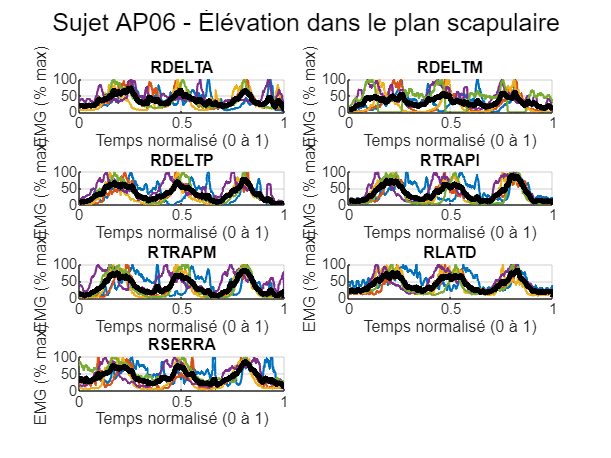

for subj_idx = 1:nb_subjects
    for a_idx = 1:nb_analytics
        % Chargement des données
        fileName = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
            '%s-%s-20240101-PROTOCOL01-ANALYTIC%d-.c3d'], ...
            subjects{subj_idx}, subjects{subj_idx}, subjects{subj_idx}, a_idx);

        c3dH = btkReadAcquisition(fileName);
        analogs = btkGetAnalogs(c3dH);
        
        % figure;
        sgtitle(sprintf('Sujet %s - %s', subjects{subj_idx}, analytic_labels{a_idx}));
        
        for m = 1:nb_muscles
            subplot(ceil(nb_muscles/2), 2, m);
            muscle_name = muscles{m};
            if isfield(analogs, muscle_name)
                signal = analogs.(muscle_name);
                time_original = linspace(0, 1, length(signal));
                
                % 1) Filtrage passe-bande
                signal_filtered = filtfilt(b, a, signal);
                % 2) Rectification
                signal_abs = abs(signal_filtered);
                % 3) Lissage avec Root Mean Square
                emg_rms = sqrt(movmean(signal_abs.^2, rms_window));
                % 4) Normalisation par maximum de chaque cycle
                num_cycles = 3;
                cycle_length = floor(length(emg_rms) / num_cycles);
                emg_normalized = zeros(size(emg_rms));
                for cycle = 1:num_cycles
                    start_idx = (cycle - 1) * cycle_length + 1;
                    end_idx = min(start_idx + cycle_length - 1, length(emg_rms));
                    sorted_vals = sort(emg_rms(start_idx:end_idx), 'descend');
                    mvc_peak_avg = mean(sorted_vals(1:5));
                    if mvc_peak_avg ~= 0
                        emg_normalized(start_idx:end_idx) = (emg_rms(start_idx:end_idx) / mvc_peak_avg) * 100;
                    end
                end

                % 5) Interpolation sur l'axe temporel normalisé
                interp_signal_analytic = interp1(time_original, emg_normalized, time_normalized, 'spline');
                
                all_analytic_data{subj_idx, a_idx, m} = interp_signal_analytic;

                % Affichage des données "ANALYTIC" traitées (si nécessaire)
                % plot(time_normalized, interp_signal_analytic, 'LineWidth', 1.2);
                title(muscle_name);
                xlabel('Temps normalisé (0 à 1)');
                ylabel('EMG (% max)');
                grid on;
            else
                title(sprintf('%s (Données absentes)', muscle_name));
            end
        end
    end
end

**Comparasions des données analytiques**

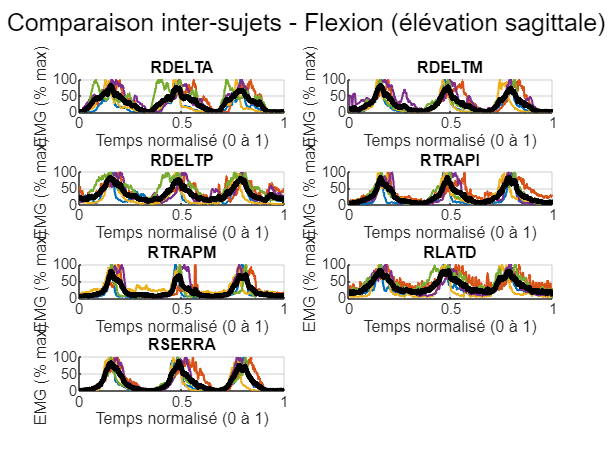

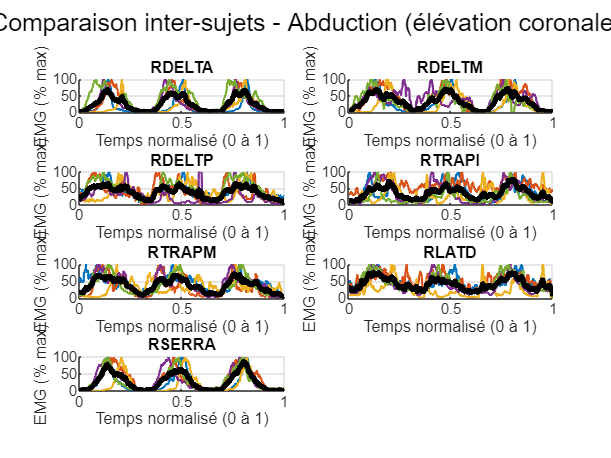

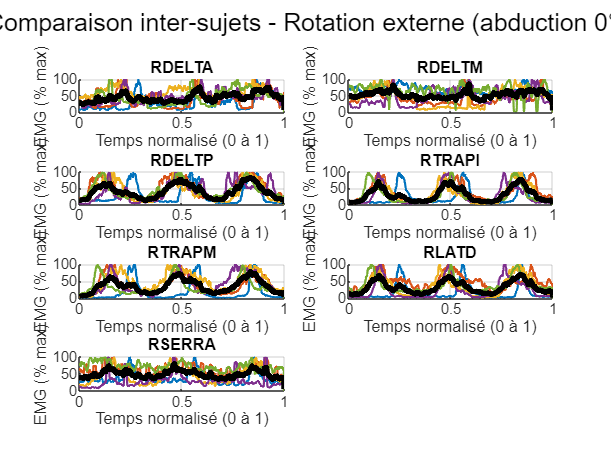

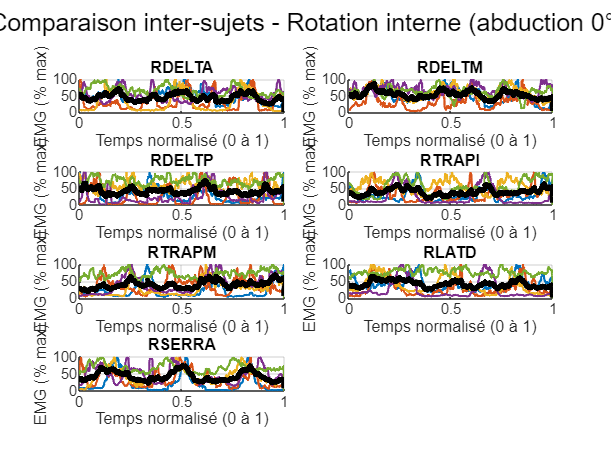

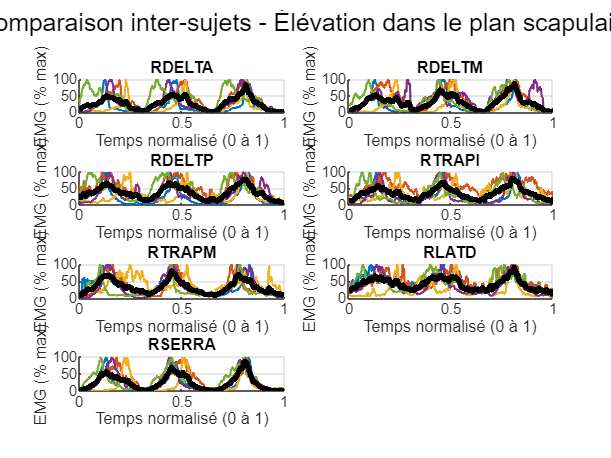

global_profiles_analytic = cell(nb_analytics, nb_muscles);

for a_idx = 1:nb_analytics
    figure;
    sgtitle(sprintf('Comparaison inter-sujets - %s', analytic_labels{a_idx}));
    
    for m = 1:nb_muscles
        all_subjects_matrix = [];  % Stocke les courbes pour ce muscle
        valid_subject_count = 0;     % Compteur des sujets valides
        
        subplot(ceil(nb_muscles/2), 2, m);
        hold on;
        
        for subj_idx = 1:nb_subjects
            if ~isempty(all_analytic_data{subj_idx, a_idx, m})
                plot(time_normalized, all_analytic_data{subj_idx, a_idx, m}, 'LineWidth', 1.2);
                all_subjects_matrix = [all_subjects_matrix; all_analytic_data{subj_idx, a_idx, m}];
                valid_subject_count = valid_subject_count + 1;
            end
        end

            mean_profile = mean(all_subjects_matrix, 1);
            global_profiles_analytic{a_idx, m} = mean_profile;
            plot(time_normalized, mean_profile, 'k', 'LineWidth', 3);
        
        title(muscles{m});
        xlabel('Temps normalisé (0 à 1)');
        ylabel('EMG (% max)');
        grid on;
        hold off;
    end
end

**Mapping des activations moyennes**

result_table = {};

for f_idx = 1:nb_analytics
    % Ligne d'en-tête pour ce functional
    header_row = cell(1, nb_muscles+1);
    header_row{1} = analytic_labels{f_idx};
    for m = 1:nb_muscles
        header_row{m+1} = muscles{m};
    end
    result_table = [result_table; header_row];
    
    for subj_idx = 1:nb_subjects
        result_row = cell(1, nb_muscles+1);
        result_row{1} = subjects{subj_idx};
        for m = 1:nb_muscles
            if ~isempty(all_analytic_data{subj_idx, f_idx, m})
                % Calcul de l'activation moyenne (arrondi)
                mean_activation = round(mean(all_analytic_data{subj_idx, f_idx, m}));
            else
                mean_activation = NaN;
            end
            result_row{m+1} = mean_activation;
        end
        result_table = [result_table; result_row];
    end
end

% Sauvegarde des résultats dans un fichier Excel
% final_table = cell2table(result_table);
% writetable(final_table, 'Activations_Analytic.xlsx', 'Sheet', 'Activations');
% 
% disp('Fichier Excel "Activations_Analytic.xlsx" créé avec succès.');

Fichier Excel "Activations_Functional.xlsx" créé avec succès.
